tic
%variables
clear
close

arrowscale=.6;
quivercolor='b';
fontsize=12;
markersize=150;
Esize=25;
quiverarrowhead=.4;
arcol=2.5;


scalestreamarrows=7;


fontweight='bold';


Fcolor=[0.5 0 1];
dScolor=[0 0.7 0.5];
Mcolor=[0.7 0.2 0.2];
Ecolor=[1 0 0];
K0color=[0 0 1];
CHcolor=[0 0 0];
dotcolor='k';


g=1;
interval=.2;
a=1;

omesh=sym(linspace(0,1,6));
olmesh=omesh;
oamesh=(nthroot(g,a+1))*omesh;
qmesh=linspace(-.9,.9,5);



genobj=hgtransform;

kneghpos=hgtransform('Parent',genobj);
kneghneg=hgtransform('Parent',genobj);
kpos=hgtransform('Parent',genobj);

transkneghpos=makehgtform('translate',[-1 0 0]);
rotkneghpos=makehgtform('zrotate',3*pi/4);
scalekneghpos=makehgtform('scale',[1 1/sqrt(2) 1]);
transbackkneghpos=makehgtform('translate',[1 1 0]);

movekneghpos=transbackkneghpos*scalekneghpos*rotkneghpos*transkneghpos;

set(kneghpos,'Matrix',movekneghpos);




rotkneghneg=makehgtform('xrotate',pi);
transkneghneg=makehgtform('translate',[1 0 0]);
rotkneghneg2=makehgtform("zrotate",-3*pi/4);
scalekneghneg=makehgtform('scale',[1 1/sqrt(2) 1]);
transbackkneghneg=makehgtform('translate',[-1 1 0]);

movekneghneg=transbackkneghneg*scalekneghneg*rotkneghneg2*transkneghneg*rotkneghneg;

set(kneghneg,'Matrix',movekneghneg);

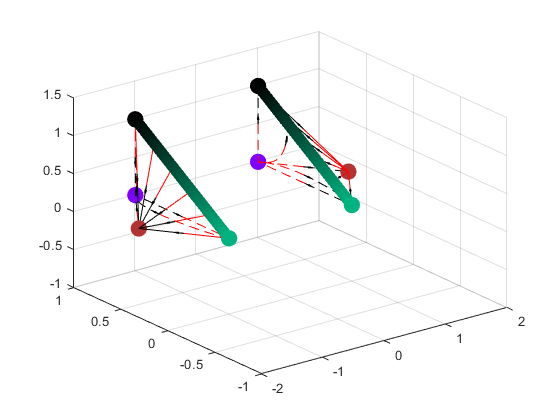






[Xtemp Ytemp Ztemp]=meshgrid(omesh,olmesh,oamesh);

X=Xtemp((Ytemp<=1-Xtemp) & (Ztemp<=(nthroot(g,a+1)*Xtemp)) & Xtemp<=1);
Y=Ytemp((Ytemp<=1-Xtemp) & (Ztemp<=(nthroot(g,a+1)*Xtemp)) & Xtemp<=1);
Z=Ztemp((Ytemp<=1-Xtemp) & (Ztemp<=(nthroot(g,a+1)*Xtemp)) & Xtemp<=1);


P=(g-1)*X-Z.^(a+1)./X.^a;
P(Z==0)=(g-1)*X(Z==0);
P(X==Z)=(g-2)*X(X==Z);

q=1/2*(3*P+X-2*Y);

U=(2*q-1).*X-3*P;
V=2*(1+q).*Y;
T=2*(1+q).*Z;

L=sqrt(U.^2+V.^2+T.^2);
L(L==0)=1;

Xsol=X(U==0 & V==0 & T==0 & (X==0 | Y==0 | Z==0));
Ysol=Y(U==0 & V==0 & T==0 & (X==0 | Y==0 | Z==0));
Zsol=Z(U==0 & V==0 & T==0 & (X==0 | Y==0 | Z==0));


dotcolors=zeros(length(Xsol),3);
dotcolors(Xsol+Ysol==1,:)=repmat(K0color,size(dotcolors(Xsol+Ysol==1,:),1),1);
dotcolors(Xsol==1 & Zsol==nthroot(g,a+1),:)=repmat(CHcolor,size(dotcolors(Xsol==1 & Zsol==nthroot(g,a+1),:),1),1);
dotcolors(Xsol==0 & Ysol==0,:)=Mcolor;
dotcolors(Xsol==1 & Ysol==0 & Zsol~=nthroot(g,a+1),:)=repmat(Fcolor,size(dotcolors(Xsol==1 & Ysol==0 & Zsol~=nthroot(g,a+1),:),1),1);
dotcolors(Xsol==0 & Ysol==1,:)=repmat(dScolor,size(dotcolors(Xsol==0 & Ysol==1,:),1),1);


% arrowcolors=double(([U./L V./L T./L]+1)/arcol);
cdx=linspace(0,1,40);
cdy=1-cdx;
cdz=nthroot(g,a+1)*cdx;

cdcolors=(1-cdx')*dScolor;

% plot3(cdx,[1 0],[0 nthroot(g,a+1)],'LineWidth',5,'Color',K0color,'Parent',kneghpos);
% plot3(-[0 1],-[1 0],-[0 nthroot(g,a+1)],'LineWidth',5,'Color',K0color,'Parent',kneghneg);

scatter3(cdx,cdy,cdz,markersize/2,cdcolors,'filled','Parent',kneghpos);
scatter3(-cdx,-cdy,-cdz,markersize/2,cdcolors,'filled','Parent',kneghneg);

scatter3(Xsol,Ysol,Zsol,markersize,dotcolors,'filled','Parent',kneghpos);
scatter3(-Xsol,-Ysol,-Zsol,markersize,dotcolors,'filled','Parent',kneghneg);



% q3Dkneghpos=quiver3D([double(X(:)),double(Y(:)),double(Z(:))],[double(U(:)./L(:)),double(V(:)./L(:)),double(T(:)./L(:))]/7,arrowcolors,quiverarrowhead);
% q3Dkneghneg=quiver3D([-double(X(:)),-double(Y(:)),-double(Z(:))],[double(U(:)./L(:)),double(V(:)./L(:)),double(T(:)./L(:))]/7,arrowcolors,quiverarrowhead);
% 
% 
% 
% set(q3Dkneghpos,'Parent',kneghpos);
% set(q3Dkneghneg,'Parent',kneghneg);
hold on


    xstart=0:.1:.5;
    ystart=.5-xstart;
    zstart=nthroot(g,a+1)*xstart;

    %Omega A = nthroot(g,a+1)*Omega streamlines
    f=@(t,x)     [(2*(-x(1)-x(2))-1)*x(1)+3*x(1);
                    2*(1+(-x(1)-x(2)))*x(2);
                    2*(1+(-x(1)-x(2)))*x(3)];
    
    for ii=1:length(xstart)
        [ta, ya]=ode45(f,[0 20],[xstart(ii) ystart(ii) zstart(ii)]);
        plot3(ya(:,1),ya(:,2),ya(:,3),'Color','k','Parent',kneghpos)
        plot3(-ya(:,1),-ya(:,2),-ya(:,3),'Color','r','Parent',kneghneg)
        hold on
        
        [ta, ya]=ode45(f,[0 -20],[xstart(ii) ystart(ii) zstart(ii)]);
        plot3(ya(:,1),ya(:,2),ya(:,3),'Color','r','Parent',kneghpos)
        plot3(-ya(:,1),-ya(:,2),-ya(:,3),'Color','k','Parent',kneghneg);
    end  
    
    X=xstart;
    Y=ystart;
    Z=zstart;
    
    
    %Omega A=0 streamlines
    f=@(t,x)     [(3*((g-1)*x(1))+x(1)-2*x(2)-1)*x(1)-3*((g-1)*x(1));
                    2*(1+1/2*(3*((g-1)*x(1))+x(1)-2*x(2)))*x(2);
                    0];
         
    xstart=[.5 .5 .5];
    ystart=[0 .5 .25];
    zstart=zeros(1,length(xstart));
    
    X=[X xstart];
    Y=[Y ystart];
    Z=[Z zstart];
    
    for ii=1:length(xstart)
        [ta, ya]=ode45(f,[0 20],[xstart(ii) ystart(ii) zstart(ii)]);
        plot3(ya(:,1),ya(:,2),ya(:,3),'--','Color','k','Parent',kneghpos)
        plot3(-ya(:,1),-ya(:,2),-ya(:,3),'--','Color','r','Parent',kneghneg)
        hold on
        
        [ta, ya]=ode45(f,[0 -20],[xstart(ii) ystart(ii) zstart(ii)]);
        plot3(ya(:,1),ya(:,2),ya(:,3),'--','Color','r','Parent',kneghpos)
        plot3(-ya(:,1),-ya(:,2),-ya(:,3),'--','Color','k','Parent',kneghneg);
    end
    

    %Omega Lambda=0 streamlines
    f=@(t,x)     [((3*((g-1)*x(1)-x(3)^(a+1)/x(1)^a)+x(1))-1)*x(1)-3*((g-1)*x(1)-x(3)^(a+1)/x(1)^a);
                    0;
                    2*(1+1/2*(3*((g-1)*x(1)-x(3)^(a+1)/x(1)^a)+x(1)))*x(3)];
         
    xstart=[1 .7];
    ystart=[0 0];
    zstart=[nthroot(g,a+1)/2 nthroot(g,a+1)/4];

    X=[X xstart];
    Y=[Y ystart];
    Z=[Z zstart];
    
    for ii=1:length(xstart)
        [ta, ya]=ode45(f,[0 20],[xstart(ii) ystart(ii) zstart(ii)]);
        plot3(ya(:,1),ya(:,2),ya(:,3),'--','Color','k','Parent',kneghpos)
        plot3(-ya(:,1),-ya(:,2),-ya(:,3),'--','Color','r','Parent',kneghneg)
        hold on
        
        [ta, ya]=ode45(f,[0 -20],[xstart(ii) ystart(ii) zstart(ii)]);
        plot3(ya(:,1),ya(:,2),ya(:,3),'--','Color','r','Parent',kneghpos)
        plot3(-ya(:,1),-ya(:,2),-ya(:,3),'--','Color','k','Parent',kneghneg);
    end
    
    P=(g-1)*X-Z.^(a+1)./X.^a;
    P(Z==0)=(g-1)*X(Z==0);
    P(X==Z)=(g-2)*X(X==Z);
    
    q=1/2*(3*P+X-2*Y);
    
    U=(2*q-1).*X-3*P;
    V=2*(1+q).*Y;
    T=2*(1+q).*Z;
    
    L=sqrt(U.^2+V.^2+T.^2);
    
    q3Dkneghpos=quiver3D([double(X(:)),double(Y(:)),double(Z(:))],[double(U(:)./L(:)),double(V(:)./L(:)),double(T(:)./L(:))]/scalestreamarrows,'k',quiverarrowhead);
    q3Dkneghneg=quiver3D([-double(X(:)),-double(Y(:)),-double(Z(:))],[double(U(:)./L(:)),double(V(:)./L(:)),double(T(:)./L(:))]/scalestreamarrows,'k',quiverarrowhead);
    
    
    
    set(q3Dkneghpos,'Parent',kneghpos);
    set(q3Dkneghneg,'Parent',kneghneg);

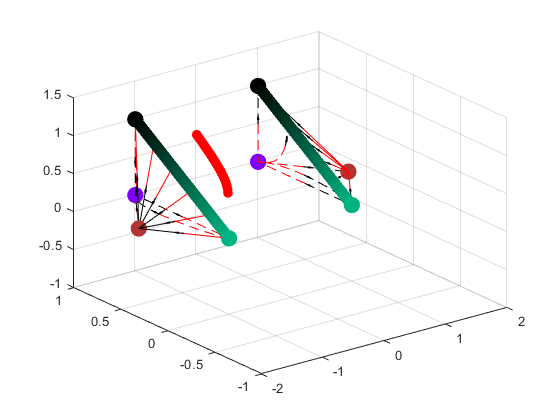

syms x real
    
    assume(x>0);
    
    eqn=(g*x^(a+1)-2/3*x^a)^(1/(a+1));
    solom=solve(eqn,x);
    if solom<=1
        plot3(0,solom,0,'.','MarkerSize',Esize,'Color',Ecolor,'Parent',kpos);
    end
    hold on
    
    solom=double(solom);
    n=.69-solom;
    
    for ii=[solom solom+n/8 solom+n/2 solom+n/1.07 linspace(.702,1,20)]
         oma=(g*ii^(a+1)-2/3*ii^a)^(1/(a+1));
         if 0<oma && oma<=nthroot(g,a+1)*ii && ii<=1
            plot3(0,ii,oma,'.','MarkerSize',Esize,'Color',Ecolor,'Parent',kpos);
            hold on
         end
    end

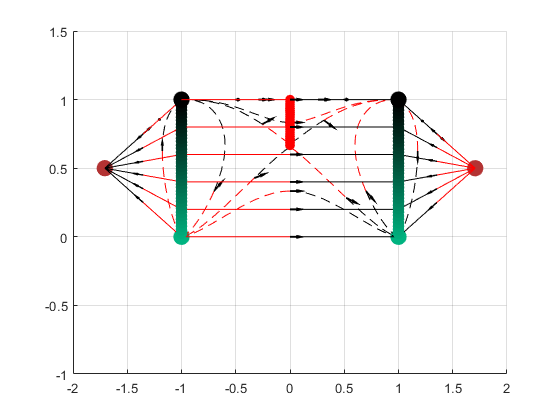


% [Xtemp Ytemp Ztemp]=meshgrid(qmesh,omesh,oamesh);
% 
% X=Xtemp(Ztemp<=(nthroot(g,a+1)*Ytemp) & Ytemp<=1);
% Y=Ytemp(Ztemp<=(nthroot(g,a+1)*Ytemp) & Ytemp<=1);
% Z=Ztemp(Ztemp<=(nthroot(g,a+1)*Ytemp) & Ytemp<=1);
% 
% P=(g-1)*Y-Z.^(a+1)./Y.^a;
% P(Z==0)=(g-1)*Y(Z==0);
% P(Y==Z)=(g-2)*Y(Y==Z);
% 
% 
% U=(X.^2-1).*(3/2*(Y+P)-1);
% V=3*X.*(Y+P).*(Y-1);
% T=3*X.*(Y+P).*Z;
% 
% L=sqrt(U.^2+V.^2+T.^2);
% L=double(L);
% L(L==0)=1;
% 
% arrowcolors=double(([U./L V./L T./L]+1)/arcol);





% q3Dkpos=quiver3D([double(X(:)),double(Y(:)),double(Z(:))],[double(U(:)./L(:)),double(V(:)./L(:)),double(T(:)./L(:))]/7,arrowcolors,quiverarrowhead);
% set(q3Dkpos,'Parent',kpos);



hold on


    %Omega A = nthroot(g,a+1)*Omega streamlines
    xstart=[0 0 0 0 0 0];
    ystart=[0 .2 .4 .6 .8 1];
    zstart=nthroot(g,a+1)*ystart; 
    
    
    X=xstart;
    Y=ystart;
    Z=zstart;

    f=@(t,x) [-(x(1)^2-1);
                0;
                0];
    
    for ii=1:length(xstart)
        [ta, ya]=ode45(f,[0 20],[xstart(ii) ystart(ii) zstart(ii)]);
        plot3(ya(:,1),ya(:,2),ya(:,3),'Color','k','Parent',kpos)
        hold on
        
        [ta, ya]=ode45(f,[0 -20],[xstart(ii) ystart(ii) zstart(ii)]);
        plot3(ya(:,1),ya(:,2),ya(:,3),'Color','r','Parent',kpos)
    end
    
    
   
    
    
    %Einstein static streamlines Omega A=0
    syms x real
    
    assume(x>0);
    eqn=(g*x^(a+1)-2/3*x^a)^(1/(a+1));
    solom=double(solve(eqn,x));
            
    f=@(t,x) [(x(1)^2-1).*(3/2*(x(2)+(g-1)*x(2)-x(3)^(a+1)/x(2)^a)-1);
                3*x(1)*((g-1)*x(2)-x(3)^(a+1)/x(2)^a+x(2))*(x(2)-1);
                3*x(1)*x(3)*(x(2)+(g-1)*x(2)-x(3)^(a+1)/x(2)^a)];
    
    

    if solom<=1
    
       [ta ya]=ode45(f,[0 20],[0 solom-.02 0]);
        plot3(ya(1:29,1),ya(1:29,2),ya(1:29,3),'--','Color','r','Parent',kpos);
        plot3(ya(29:end,1),ya(29:end,2),ya(29:end,3),'--','Color','k','Parent',kpos);
        
        X=[X ya(29,1)];
        Y=[Y ya(29,2)];
        Z=[Z ya(29,3)];
        
        [ta ya]=ode45(f,[0 -20],[0 solom-.02 0]);
        plot3(ya(1:27,1),ya(1:27,2),ya(1:27,3),'--','Color','k','Parent',kpos)
        plot3(ya(27:end,1),ya(27:end,2),ya(27:end,3),'--','Color','r','Parent',kpos)
        
        X=[X ya(27,1)];
        Y=[Y ya(27,2)];
        Z=[Z ya(27,3)];
        
        [ta ya]=ode45(f,[0 20],[0 solom+.02 0]);
    
        plot3(ya(1:26,1),ya(1:26,2),ya(1:26,3),'--','Color','r','Parent',kpos);
        plot3(ya(26:end,1),ya(26:end,2),ya(26:end,3),'--','Color','k','Parent',kpos);
        
        X=[X ya(26,1)];
        Y=[Y ya(26,2)];
        Z=[Z ya(26,3)];
        
        [ta ya]=ode45(f,[0 -20],[0 solom+.02 0]);
        plot3(ya(1:27,1),ya(1:27,2),ya(1:27,3),'--','Color','k','Parent',kpos)
        plot3(ya(27:end,1),ya(27:end,2),ya(27:end,3),'--','Color','r','Parent',kpos)
        
        X=[X ya(27,1)];
        Y=[Y ya(27,2)];
        Z=[Z ya(27,3)];
    
    end
    
    
     %Einstein static streamlines  Lambda=0
    
    f=@(t,x)   [(x(1)^2-1)*(1/2*(x(2)-3*x(3)^(a+1)/x(2)^a)-(1-x(2)));
                x(1)*(x(2)*(x(2)-3*x(3)^(a+1)/x(2)^a-2*(1-x(2)))-x(2)+3*x(3)^(a+1)/x(2)^a);
                2*x(1)*x(3)*(1+1/2*(x(2)-3*x(3)^(a+1)/x(2)^a)-(1-x(2)))];
            
    om=1;
    if (g*om^(a+1)-2/3*om^a)>=0
        oma=(g*om^(a+1)-2/3*om^a)^(1/(1+a));
        plot3(0,om,oma,'.','MarkerSize',Esize,'Color',Ecolor,'Parent',kpos);
        
        [ta ya]=ode45(f,[0 20],[0 1 oma-0.02]);
    
        plot3(ya(1:26,1),ya(1:26,2),ya(1:26,3),'--','Color','r','Parent',kpos);
        plot3(ya(26:end,1),ya(26:end,2),ya(26:end,3),'--','Color','k','Parent',kpos);
        
        X=[X ya(27,1)];
        Y=[Y ya(27,2)];
        Z=[Z ya(27,3)];
        
        [ta ya]=ode45(f,[0 -20],[0 1 oma-0.02]);
        plot3(ya(1:27,1),ya(1:27,2),ya(1:27,3),'--','Color','k','Parent',kpos)
        plot3(ya(27:end,1),ya(27:end,2),ya(27:end,3),'--','Color','r','Parent',kpos)
        
        X=[X ya(27,1)];
        Y=[Y ya(27,2)];
        Z=[Z ya(27,3)];
        
         [ta ya]=ode45(f,[0 20],[0 1 oma+0.02]);
    
        plot3(ya(1:26,1),ya(1:26,2),ya(1:26,3),'--','Color','r','Parent',kpos);
        plot3(ya(26:end,1),ya(26:end,2),ya(26:end,3),'--','Color','k','Parent',kpos);
        
        X=[X ya(27,1)];
        Y=[Y ya(27,2)];
        Z=[Z ya(27,3)];
        
        [ta ya]=ode45(f,[0 -20],[0 1 oma+0.02]);
        plot3(ya(1:27,1),ya(1:27,2),ya(1:27,3),'--','Color','k','Parent',kpos)
        plot3(ya(27:end,1),ya(27:end,2),ya(27:end,3),'--','Color','r','Parent',kpos)
        
        X=[X ya(27,1)];
        Y=[Y ya(27,2)];
        Z=[Z ya(27,3)];
    end        
    
    
    
     f=@(t,x) [(x(1)^2-1).*(3/2*(x(2)+(g-1)*x(2)-x(3)^(a+1)/x(2)^a)-1);
                3*x(1)*((g-1)*x(2)-x(3)^(a+1)/x(2)^a+x(2))*(x(2)-1);
                3*x(1)*x(3)*(x(2)+(g-1)*x(2)-x(3)^(a+1)/x(2)^a)];
    
    k0omega=.6:.1:.9;
    
    xstart=[0 -ones(1,length(k0omega)) ones(1,length(k0omega))];
    ystart=[1 k0omega k0omega];
    zstart=[0 (k0omega-.5)*nthroot(g,a+1) (k0omega-.5)*nthroot(g,a+1)];
    
    X=[X xstart];
    Y=[Y ystart];
    Z=[Z zstart];
    
    if g>=2/3
        xstart=[xstart -.7 .7 -.5 .5 0 0 0 0];
        ystart=[ystart solom/2 solom/2 1 1 solom/2 (1+solom)/2 1 1];
        zstart=[zstart 0 0 oma/2 oma/2 0 0 oma/2 (1+oma)/2];
        
        X=[X xstart];
        Y=[Y ystart];
        Z=[Z zstart];
    elseif g<2/3
        xstart=[xstart 0 0 0 0 0];
        ystart=[ystart .4 .8 1 1 .8];
        zstart=[zstart 0 0 (nthroot(g,a+1)-.2)/2 (nthroot(g,a+1)-.2) .1];
        
        X=[X xstart];
        Y=[Y ystart];
        Z=[Z zstart];
    end
          
           
           
    for ii=1:length(xstart)
       [ta ya]=ode45(f,[0 20],[xstart(ii), ystart(ii), zstart(ii)]);
       plot3(ya(:,1),ya(:,2),ya(:,3),'--','Color','k','Parent',kpos);
       hold on
       
           
       [ta ya]=ode45(f,[0 -20],[xstart(ii), ystart(ii), zstart(ii)]);
       plot3(ya(:,1),ya(:,2),ya(:,3),'--','Color','r','Parent',kpos);
    end    
    
    
    g=sym(2/3);


    P=(g-1)*Y-Z.^(a+1)./Y.^a;
    P(Z==0)=(g-1)*Y(Z==0);
    P(Y==Z)=(g-2)*Y(Y==Z);
    
    
    U=(X.^2-1).*(3/2*(Y+P)-1);
    V=3*X.*(Y+P).*(Y-1);
    T=3*X.*(Y+P).*Z;
    
    L=sqrt(U.^2+V.^2+T.^2);
    
    q3Dkpos=quiver3D([double(X(:)),double(Y(:)),double(Z(:))],[double(U(:)./L(:)),double(V(:)./L(:)),double(T(:)./L(:))]/scalestreamarrows,'k',quiverarrowhead);
    set(q3Dkpos,'Parent',kpos);
    
% add=.2;    
% axis([-1-add 1+add -add 1+add -add nthroot(g,a+1)+add]);

% axis tight
view(0,90)

toc

Elapsed time is 3.294745 seconds.


% % view(0,90)
% % %     h=gcf;
% % %     set(h,'PaperOrientation','landscape');
% % %     print('3dsubs','-djpeg', '-r600');
% % 
% % hold on
% 
% 
% add=.2;    
% axis([-1.7-add 1.7+add -add 1+add -add nthroot(g,a+1)+add]);
% view(-11,50)
% grid off
% axis off
% if g>2/3
%     text([-1.85 1.8],[.5 .5],[0 0],{'M_-','M_+'},'FontSize',fontsize,'FontWeight',fontweight)
%     text([-1 1],[0 0],[-.2 -.2],{'dS_-','dS_+'},'FontSize',fontsize,'FontWeight',fontweight)
%     text([-1.08 .91],[1.05 1.05],[0 0],{'F_-','F_+'},'FontSize',fontsize,'FontWeight',fontweight)
%     text([-1 1],[1.1 1.1],[1 1],{'CH_-','CH_+'},'FontSize',fontsize,'FontWeight',fontweight)
%     text(0,1.1,.6,'E','FontSize',fontsize,'FontWeight',fontweight)
%     text([-.95 1.05],[0.5 0.5],[0.4 0.45],{'CD_-','CD_+'},'FontSize',fontsize,'FontWeight',fontweight)
% elseif g<2/3
%     text([-1.85 1.8],[.5 .5],[0 0],{'M_-','M_+'},'FontSize',fontsize,'FontWeight',fontweight)
%     text([-1 1],[0 0],[-.2 -.2],{'dS_-','dS_+'},'FontSize',fontsize,'FontWeight',fontweight)
%     text([-1.08 .91],[1.05 1.05],[0 0],{'F_-','F_+'},'FontSize',fontsize,'FontWeight',fontweight)
%     text([-1 1],[1.1 1.1],[nthroot(g,a+1) nthroot(g,a+1)],{'CH_-','CH_+'},'FontSize',fontsize,'FontWeight',fontweight)
%     text([-.95 .83],[0.5 0.5],[0.4 0.42],{'CD_-','CD_+'},'FontSize',fontsize,'FontWeight',fontweight)
% end
% 
% %     h=gcf;
% %     set(h,'PaperOrientation','landscape');
%     print('3dgg23','-depsc', '-r600');
% 

